clear all

**Grid**

elem_pitch = 0.30e-3;

pml_x_size = 40;                % [grid points]
pml_y_size = 40;                % [grid points]
    
% set total number of grid points not including the PML
Nx = 1024 - 2 * pml_x_size;      % [grid points]
Ny = 2048 - 2 * pml_y_size;      % [grid points]
    
PML_size = [pml_x_size pml_y_size]; 

ratio = 8; % [?]
dy = elem_pitch/ratio;          % grid point spacing in the y direction [m]
dx = dy;
kgrid = kWaveGrid(Nx, dx, Ny, dy);

**Medium**

c0 = 1540;
kgrid.Nt = 27412;
kgrid.dt = 256e-12;
medium.PMLSize = 40;
medium.sound_speed = 1540;  % [m/s]
medium.density = 1000;

**Transducer**

focal_distance = 14e-3;   % center of circle
focal_number = 2;
nAperture = (focal_distance/focal_number)/dy;
nAperture = ratio*floor(nAperture/ratio);

% ondaplana
nApertureEle =  nAperture/ratio;
nAperture = nApertureEle*ratio;

nLines = floor(Ny/ratio); % vary slightly plm_y to get nLines=128
    
bf_data_final = nan(kgrid.Nt ,nLines);

**Inclusion**

% Inclusion

radius =     2.1600    2.0000    2.7200    2.9600    3.1200    1.3867    2.8533    2.7733    0.9867    0.8267


    radius_meters = (randi([6 10])/10)*(randi([16 24],1,2)/20)*1e-2; %[0.6-1.2]
    center_meters = [randi([0 38])/10 randi([16 24])/10]*1e-2;

    radius = radius_meters/dx;
    center = center_meters/dx + [0 offset];
    
    [xGrid, yGrid] = meshgrid(1:Ny, 1:Nx);
    
    distFromCenter = sqrt((xGrid - center(1)).^2 / radius(1)^2 + (yGrid - center(2)).^2 / radius(2)^2);
    circleMatrix = double(distFromCenter <= 1);


    % Density
    density_mean = zeros(size(circleMatrix));
    density_mean(circleMatrix == 0) = rho_mean(1);
    density_mean(circleMatrix == 1) = rho_mean(2);
    
    density_std = zeros(size(circleMatrix));
    density_std(circleMatrix == 0) = rho_std(1);
    density_std(circleMatrix == 1) = rho_std(2);
    
    medium.density = patterns(density_mean, density_std, 'homo', [], Nx, Ny);
    
    % Attenuation
    alpha_coeff_mean = zeros(size(circleMatrix));
    alpha_coeff_mean(circleMatrix == 0) = alpha_mean(1);
    alpha_coeff_mean(circleMatrix == 1) = alpha_mean(2);
    
    alpha_coeff_std = zeros(size(circleMatrix));
    alpha_coeff_std(circleMatrix == 0) = alpha_std(1);
    alpha_coeff_std(circleMatrix == 1) = alpha_std(2);
    
    medium.alpha_coeff = patterns(alpha_coeff_mean, alpha_coeff_std, 'homo', [], Nx, Ny);
    
    medium.alpha_power = 1;
    medium.alpha_mode = 'no_dispersion';
    
    source_strength = 1e6;
    tone_burst_freq = 6e6;        % [Hz]
    tone_burst_cycles = 3.5;
    
    rho0 = 1000;

    for ii = 1:nLines
    
        jj = ratio*ii;
        axis_x = rz(:,1);
        axis_y = rx(1,:);
        disp(['Lines: ',num2str(ii),' de ',num2str(nLines)]);
        src_ini = max(1,jj - nAperture/2) ;
        src_fin = min(Ny,jj + nAperture/2-1) ;
    
        [temp,pos] = min(abs(axis_x-focal_distance));
        focus_point = [axis_y(jj) axis_x(pos)];
    
        aperture_point_src = [axis_y(src_ini:src_fin)' axis_x(offset)*ones(src_fin-src_ini+1,1)];
    
        figure (6); plot(aperture_point_src(:,1),aperture_point_src(:,2),'sb');
        hold on; plot(focus_point(:,1),focus_point(:,1),'sr'); hold off;
    
    %%
        sensor.mask = zeros(Nx, Ny);
        % Need a slight offset here to prevent backwards propagating pulse
        sensor.mask(offset, src_ini:ratio:src_fin) = 1;
        %sensor.directivity_size = 0.2698e-3;
        %sensor.directivity_angle = zeros(size(sensor.mask));
        %sensor.directivity_size = 0.4e-3;
        sensor.directivity_size = 10*kgrid.dx;
        sensor.directivity_angle = zeros(size(sensor.mask));
    %%
     %amp = 100000; % [au]
        source.p_mask = zeros(Nx, Ny);
        source.p_mask(offset,src_ini:src_fin) = 1;
        apod = boxcar(nnz(source.p_mask));
    
        input_signal_norm = toneBurst(1/kgrid.dt, tone_burst_freq, tone_burst_cycles);
        input_signal = (source_strength ./ (c0 * rho0)) .* input_signal_norm;
    
        %excitation = amp*toneBurst(1/kgrid.dt,6.66*1e6,5);
        %src_exc = apod(:)*excitation(:)';
        src_exc = apod(:)*input_signal(:)';
    
        angle = 0;
        %source.p1 = steer_delay(src_exc,angle,dy,dt,1540);
        %figure; imagesc(src_exc);
        %figure; imagesc(source.p1);
        %source = steer_delay_focus(src_exc,angle,dy,kgrid.dt,1540,aperture_point_src,focus_point);
        %source3 = steer_delay_focus(src_exc,angle,dy,kgrid.dt,1540,aperture_point_src,[0 Inf]);
        source.p = src_exc;
        %figure; imagesc(source.p2);
        %source.p = source.p2;
    
        medium.sound_speed_ref = 1540;
        
        
        %%
            %PML_alpha = 2;   % Default is 2
        %DATA_CAST       = 'single';     % set to 'single' or 'gpuArray-single' to speed up computations
        %input_args = {'PMLInside', false, 'PMLAlpha', PML_alpha, 'PMLSize', PML_size, 'PlotPML', false,...
        %    'Smooth', false,'PlotSim',false, 'DataCast',DATA_CAST, 'DataRecast', true};
        input_args = {'PMLInside', false, 'PMLSize', PML_size, ... %'PMLAlpha', PML_alpha, ...
            'DataCast',DATA_CAST, 'DataRecast', true, 'PlotSim',false};
    
        % run the simulation
        %colormap gray
        sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});
    
        sensor_data=sensor_data';
        %%
        
          max_apert = 64; % elements
        f_number = 2;
        c_bf = 1540;
        bf_data = BFangle(sensor_data,max_apert,fs,c_bf,elem_pitch,'rect',f_number,0);
    
        if src_ini <= 1
            index = size(bf_data,2) - floor(nApertureEle/2);
        elseif src_fin>= Ny
            index = floor(nApertureEle/2)+1;
        else
            index = floor(nApertureEle/2)+1;
        end
    
        bf_data_final(:,ii) = bf_data(:,index);
    
    end

dsadasd

Nx_tot = Nx;
Ny_tot = Ny;
rx = ones(Nx_tot,1)*linspace(-Ny_tot*dy/2,Ny_tot*dy/2,Ny_tot);
rz = linspace(0,Nx_tot*dx,Nx)'*ones(1,Ny_tot);

rx(end)*2

ans = 0.0738

rz(end)

ans = 0.0354


c0 = 1540;
t_end = (Nx*dx)*2/c0;     % [s]
kgrid.makeTime(c0, [], t_end);

fs = 1/kgrid.dt;
fs*1e-6

ans = 136.8889


nLines = floor(Ny/ratio); % vary slightly plm_y to get nLines=
axAxis = 0:(kgrid.Nt-1); axAxis = axAxis*1/fs*c0/2;
latAxis = 0:(nLines-1);
latAxis = latAxis-mean(latAxis);
latAxis = latAxis*elem_pitch;

z = axAxis(100:end)

z =     0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008    0.0008


x = latAxis

x =    -0.0367   -0.0364   -0.0361   -0.0358   -0.0355   -0.0352   -0.0349   -0.0347   -0.0343   -0.0340   -0.0337   -0.0334   -0.0331   -0.0328   -0.0325   -0.0322   -0.0319   -0.0316   -0.0313   -0.0310   -0.0307   -0.0304   -0.0301   -0.0298   -0.0295   -0.0292   -0.0289   -0.0286   -0.0283   -0.0280   -0.0277   -0.0274   -0.0271   -0.0268   -0.0265   -0.0262   -0.0259   -0.0256   -0.0253   -0.0250   -0.0247   -0.0244   -0.0241   -0.0238   -0.0235   -0.0232   -0.0229   -0.0226   -0.0223   -0.0220



focal_distance = 20e-3;

sos_mean = 1540;
sos_std = 0;

alpha_mean = randi([8 36],1,2)/20 %[0.4 1.8]; %Atenuacion del polietileno

alpha_mean =     1.4500    0.7500


alpha_std = [0 0];

rho_mean = randi([18 25],1,2)*100/2 %[1000 1000 1000 1000 1000];

rho_mean =         1100        1150


rho_std = randi([2 10],1,2)/200 %[0.01 0.06];

rho_std =     0.0500    0.0500



offset = 5;

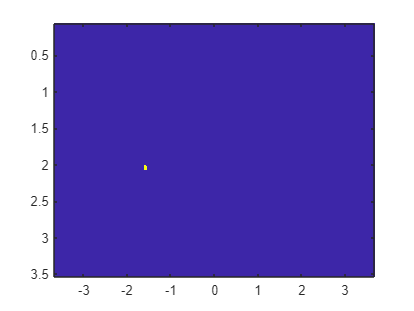

% 15 250 um
% 6 60
figure;
for i =1:50
    [xGrid, yGrid] = meshgrid(1:Ny, 1:Nx);
    radius = randi([6 60],1,1)/2; %/2 radio
    centers = [randi([0 Nx]) randi([0 Ny])];
    distFromCenter = sqrt((xGrid - center(1)).^2 / radius^2 + (yGrid - center(2)).^2 / radius^2);
    circleMatrix = double(distFromCenter <= 1);
    imagesc(x*1e2, z*1e2, circleMatrix);hold on;
end

% radius = (randi([6 10])/10)*(randi([16 24],1,2)/20)*1e-2/dx % [0.6-1.2]*[80% 120%]
% center = [randi([0 38])/10 randi([16 24])/10]*1e-2/dx + [0 offset]%
% 
% 
% 
% distFromCenter = sqrt((xGrid - center(1)).^2 / radius(1)^2 + (yGrid - center(2)).^2 / radius(2)^2);
% circleMatrix = double(distFromCenter <= 1);
% 
% figure;imagesc(x*1e2, z*1e2, circleMatrix)

% SoS
%medium.sound_speed = patterns(sos_mean, sos_std, 'homo', [], Nx, Ny);

% Density
% density_mean = zeros(size(circleMatrix));
% density_mean(circleMatrix == 0) = rho_mean(1);
% density_mean(circleMatrix == 1) = rho_mean(2);
% 
% density_std = zeros(size(circleMatrix));
% density_std(circleMatrix == 0) = rho_std(1);
% density_std(circleMatrix == 1) = rho_std(2);
% 
% medium.density = patterns(density_mean, density_std, 'homo', [], Nx, Ny);


%figure
%imagesc(x*1e3,z*1e3,medium.density); colorbar;

% Attenuation
% alpha_coeff_mean = zeros(size(circleMatrix));
% alpha_coeff_mean(circleMatrix == 0) = alpha_mean(1);
% alpha_coeff_mean(circleMatrix == 1) = alpha_mean(2);
% 
% alpha_coeff_std = zeros(size(circleMatrix));
% alpha_coeff_std(circleMatrix == 0) = alpha_std(1);
% alpha_coeff_std(circleMatrix == 1) = alpha_std(2);
% 
% medium.alpha_coeff = patterns(alpha_coeff_mean, alpha_coeff_std, 'homo', [], Nx, Ny);
% 
% figure
% imagesc(x*1e3,z*1e3, alpha_coeff_mean); colorbar;
% 
% medium.alpha_power = 1;
% medium.alpha_mode = 'no_dispersion';

function [med, med_mean, med_std] = patterns(var_mean, var_std, patt_type,var_params, Nx, Ny)
    switch patt_type
        case 'homo'
            med_mean = var_mean;
            med_std = var_std;
        case 'circle'
            circle_ind = boolean(makeDisc(Nx, Ny,...
                round(var_params.center_depth/var_params.dx)+var_params.offset, Ny/2, ...
                round(var_params.radius_disk/var_params.dx)));
            med_mean = var_mean(1)*(~circle_ind) + var_mean(2)*(circle_ind);
            med_std = var_std(1)*(~circle_ind) + var_std(2)*(circle_ind);
        case 'layers_vert'
            layer_pos = var_params.layer_pos/var_params.dx;
            [X,~] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(X<layer_pos) ...
                + var_mean(2)*(X>=layer_pos);
            med_std = var_std(1)*(X<layer_pos) ...
                + var_std(2)*(X>=layer_pos);
        case 'layers_horz'
            layer_pos = var_params.layer_pos/var_params.dy;
            [~,Y] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(Y<layer_pos) ...
                + var_mean(2)*(Y>=layer_pos);
            
            med_std = var_std(1)*(Y<layer_pos) ...
                + var_std(2)*(Y>=layer_pos);
        case 'layers_vert3'
            layer_pos = var_params.layer_pos/var_params.dx;
            [X,~] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(X<layer_pos(1)) ...
                + var_mean(2)*((X<layer_pos(2))&(X>=layer_pos(1)))...
                + var_mean(3)*(X>=layer_pos(2));
            med_std = var_std(1)*(X<layer_pos(1)) ...
                + var_std(2)*((X<layer_pos(2))&(X>=layer_pos(1)))...
                + var_std(3)*(X>=layer_pos(2));
        case 'layers_horz3'
            layer_pos = var_params.layer_pos/var_params.dy;
            [~,Y] = meshgrid(1:Ny, 1:Nx);
            med_mean = var_mean(1)*(Y<layer_pos(1)) ...
                + var_mean(2)*((Y<layer_pos(2))&(Y>=layer_pos(1)))...
                + var_mean(3)*(Y>=layer_pos(2));
            med_std = var_std(1)*(Y<layer_pos(1)) ...
                + var_std(2)*((Y<layer_pos(2))&(Y>=layer_pos(1)))...
                + var_std(3)*(Y>=layer_pos(2));
        case 'circleN'
            circle_ind = nan(Nx, Ny, length(var_params.center_depth));
            bg_mask = ones(Nx, Ny);

            med_mean = zeros(Nx, Ny);
            med_std = zeros(Nx, Ny);
            for cc = 1:length(var_params.center_depth)
                circle_ind(:,:,cc) = boolean(makeDisc(Nx, Ny,...
                    round(var_params.center_depth(cc)/var_params.dx)+var_params.offset, var_params.center_lat(cc), ...
                    round(var_params.radius_disk(cc)/var_params.dx)));
                med_mean = med_mean + var_mean(cc)*(circle_ind(:,:,cc));
                med_std = med_std + var_std(cc)*(circle_ind(:,:,cc));
                bg_mask = bg_mask & not(circle_ind(:,:,cc));
            end
            med_mean = med_mean + var_mean(end)*(bg_mask);
            med_std = med_std + var_std(end)*(bg_mask);
        case 'ellipse'
            circle_ind = nan(Nx, Ny, length(var_params.center_depth));
            bg_mask = ones(Nx, Ny);

            med_mean = zeros(Nx, Ny);
            med_std = zeros(Nx, Ny);
            for cc = 1:length(var_params.center_depth)
                circle_ind(:,:,cc) = boolean(makeDisc(Nx, Ny,...
                    round(var_params.center_depth(cc)/var_params.dx)+var_params.offset, var_params.center_lat(cc), ...
                    round(var_params.radius_disk(cc)/var_params.dx)));
                med_mean = med_mean + var_mean(cc)*(circle_ind(:,:,cc));
                med_std = med_std + var_std(cc)*(circle_ind(:,:,cc));
                bg_mask = bg_mask & not(circle_ind(:,:,cc));
            end
            med_mean = med_mean + var_mean(end)*(bg_mask);
            med_std = med_std + var_std(end)*(bg_mask);
        
        otherwise
            med_mean = 0;
            med_std = 0;
            warning('Unexpected type')
    end
    med = med_mean + med_mean.*med_std.*randn(Nx, Ny);
end